clear
close all
load DelMar_data.mat
whos

  Name            Size                Bytes  Class       Attributes

  T               1x13682            109456  double                
  readme          1x93                  186  char                  
  t           13682x1                109456  datetime              
  u               8x13682            875648  double                
  v               8x13682            875648  double                
  z               8x1                    64  double                



**Plot time series of u (positive east, Figure 1) current components for all depths.**

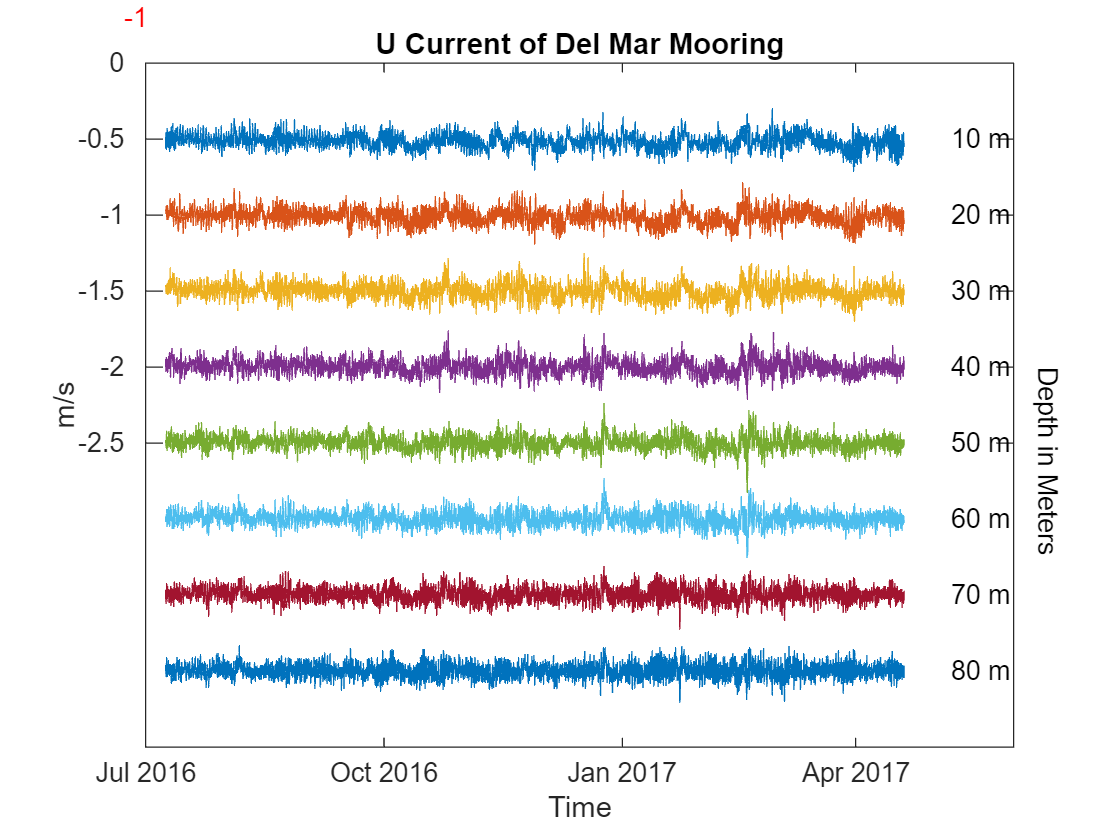

figure(1);
clf;

for i = 1:height(u)
    plot(t,u(i,:)+z(i)*0.05);
    text(t(end)+18,-(i-1)*.5-.5,[num2str(abs(z(i))),' m'])
    hold on
end

text(t(1)-15,2.5-1.3,[num2str(1)], 'Color', 'r')
text(t(1)-16,1.5-1.2,[num2str(-1)], 'Color', 'r')
hold off;
datetick;

h = text(t(end)+55,-3*.5-.5, 'Depth in Meters');
set(h, 'Rotation', 270);

set(gca, 'YTick', -2.5:0.5:3.5); 
set(gca, 'YTickLabel', num2str((-2.5:0.5:3.5)')); 

xlabel('Time')
datetick('x', 'mmm yyyy', 'keeplimits');
ylabel('m/s')
title('U Current of Del Mar Mooring')

**Plot time series of v (positive north, Figure 2) current components for all depths.**

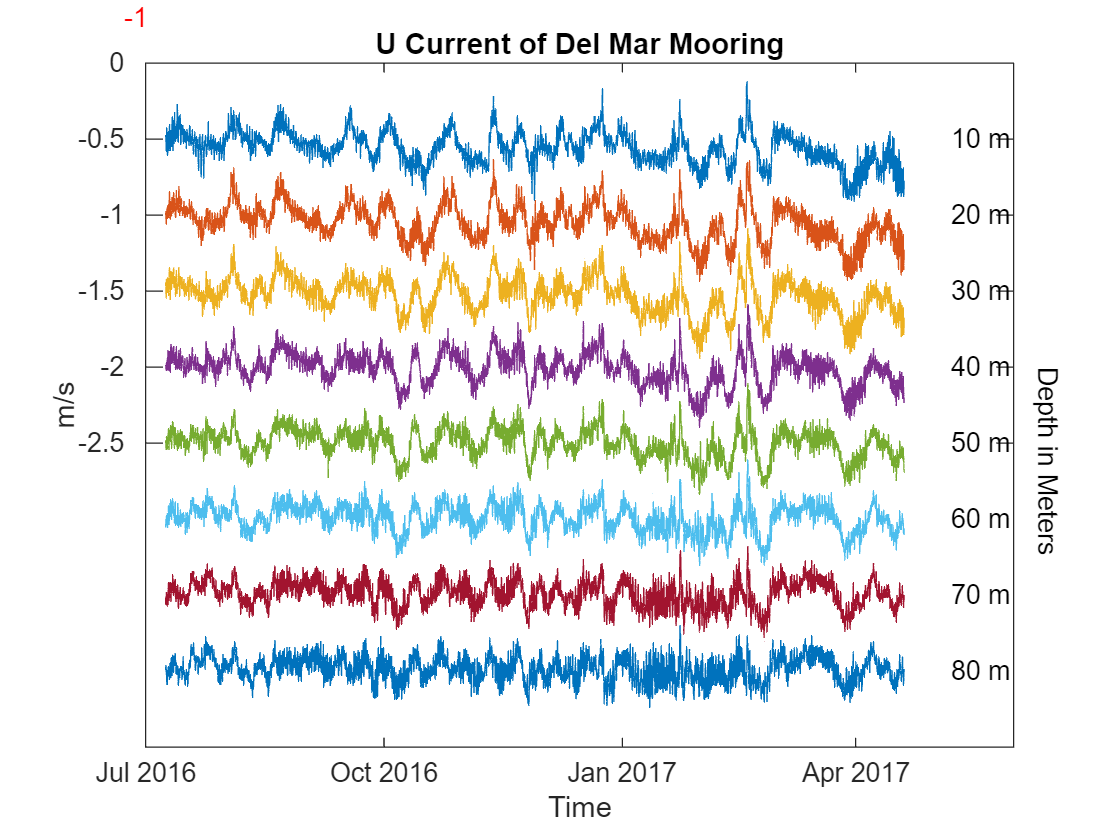

figure(2);
clf

for i = 1:height(v)
    plot(t,v(i,:)+z(i)*0.05);
    text(t(end)+18,-(i-1)*.5-.5,[num2str(abs(z(i))),' m'])
    hold on
end

text(t(1)-15,2.5-1.3,[num2str(1)], 'Color', 'r')
text(t(1)-16,1.5-1.2,[num2str(-1)], 'Color', 'r')
hold off;
datetick;

h = text(t(end)+55,-3*.5-.5, 'Depth in Meters');
set(h, 'Rotation', 270);

set(gca, 'YTick', -2.5:0.5:3.5); 
set(gca, 'YTickLabel', num2str((-2.5:0.5:3.5)')); 

xlabel('Time')
datetick('x', 'mmm yyyy', 'keeplimits');
ylabel('m/s')
title('U Current of Del Mar Mooring')

**Q1: Describe qualitatively the time-depth variability of u and v.**

The time-depth variability of the u and v current components shows consistent oscillations with some fluctuations across the depths (10–80 m) from July 2016 to May 2017. Both components display consistent wave-like amplitude fluctuations, with the currents closer to the surface responding more visibly to atmospheric forces, while deeper currents show a more damped or delayed response, possibly due to reduced energy transfer. At times, bursts of stronger currents occur. Overall, the current patterns are mostly uniform.

**Compute EOFs of the combined u and v currents.**

**Plot the mode number (x-axis) vs the percentage of total variance explained by each mode (y-axis) (Figure 3).**

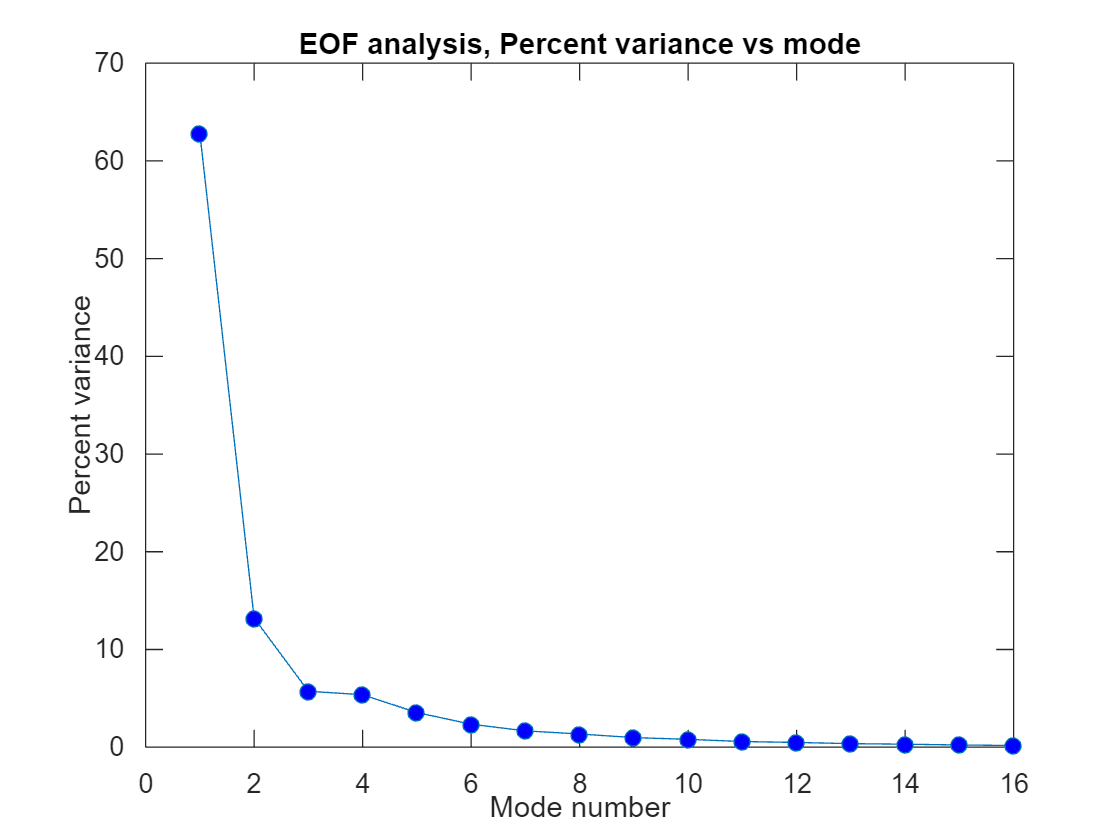

combined_data = [u; v]; 
C = cov(combined_data'); % Transpose to get time series as columns

% Perform EOF analysis (Eigen decomposition)
[eigenvectors, eigenvalues] = eig(C);
lambda = diag(eigenvalues); % Extract eigenvalues into a vector

% Sort eigenvalues and corresponding eigenvectors in descending order
[lambda, sorted_indices] = sort(lambda, 'descend');
eigenvectors = eigenvectors(:, sorted_indices);

percent_var = (lambda / sum(lambda)) * 100;

figure(3);
plot(1:length(percent_var), percent_var, '-o', 'MarkerFaceColor', 'b');
xlabel('Mode number');
ylabel('Percent variance');
title('EOF analysis, Percent variance vs mode');
xlim([0 16]); 

**Plot the PCs (temporal expansions) of the first 4 modes and indicate the total variance explained by each mode (Figure 4).**

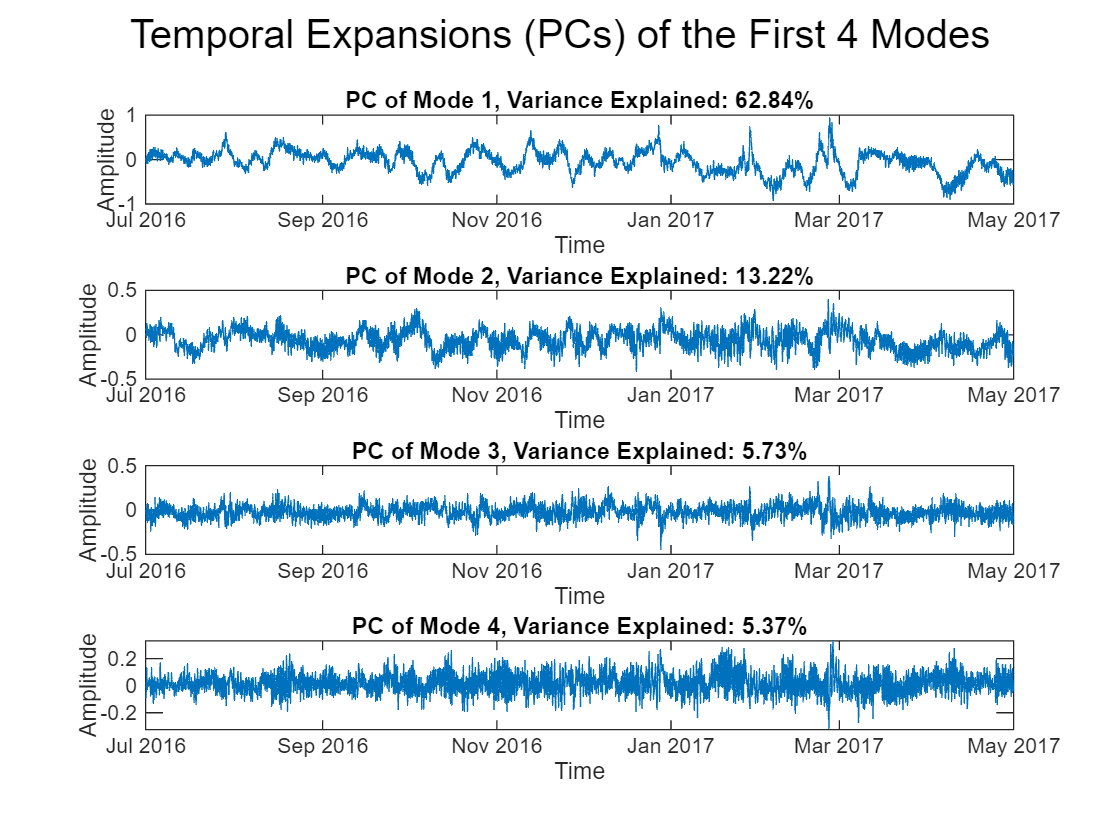

PCs = eigenvectors'* combined_data; 

start_date = datetime(2016, 7, 1);
end_date = datetime(2017, 5, 1);
time_vector = linspace(start_date, end_date, size(PCs, 2)); 

figure(4);
for i = 1:4
    subplot(4, 1, i); % Subplots for each mode
    plot(time_vector, PCs(i, :));
    title(['PC of Mode ' num2str(i) ', Variance Explained: ' num2str(percent_var(i), '%.2f') '%']);
    xlabel('Time');
    ylabel('Amplitude');
end

sgtitle('Temporal Expansions (PCs) of the First 4 Modes');

**Plot u and v EOF amplitudes vs depth for the first 4 modes (Figure 5). **

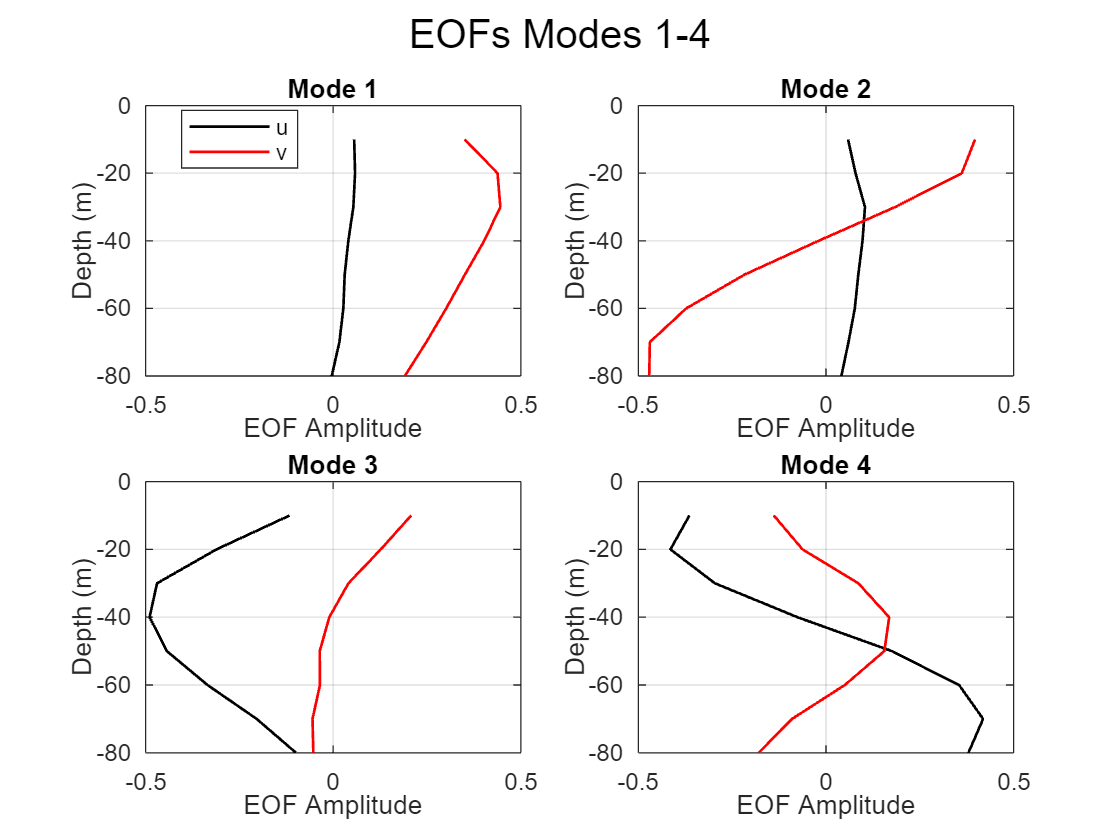

num_modes = 4;
num_depths = size(u, 1);
depth = linspace(-10, -80, num_depths); 

u_eof_amp = eigenvectors(1:num_depths, 1:num_modes); % u EOFs for the first 4 modes
v_eof_amp = eigenvectors(num_depths+1:end, 1:num_modes); % v EOFs for the first 4 modes

figure (5);
for i = 1:num_modes
    subplot(2, 2, i); % 2x2 grid
    plot(u_eof_amp(:, i), depth, 'k-', 'LineWidth', 1, 'DisplayName', 'u'); 
    hold on;
    plot(v_eof_amp(:, i), depth, 'r-', 'LineWidth', 1, 'DisplayName', 'v');
    hold off;

    set(gca, 'YDir', 'normal'); 
    xlabel('EOF Amplitude');
    ylabel('Depth (m)');
    title(['Mode ' num2str(i)]);
    xlim([-0.5, 0.5]); 
    grid on

    % Add legend only for the first subplot
    if i == 1
        legend('show', 'Location', 'best');
    end
end

sgtitle('EOFs Modes 1-4');

**Plot the percent of and u and v variance explained at each depth for the first 4 modes (Figure 6) **

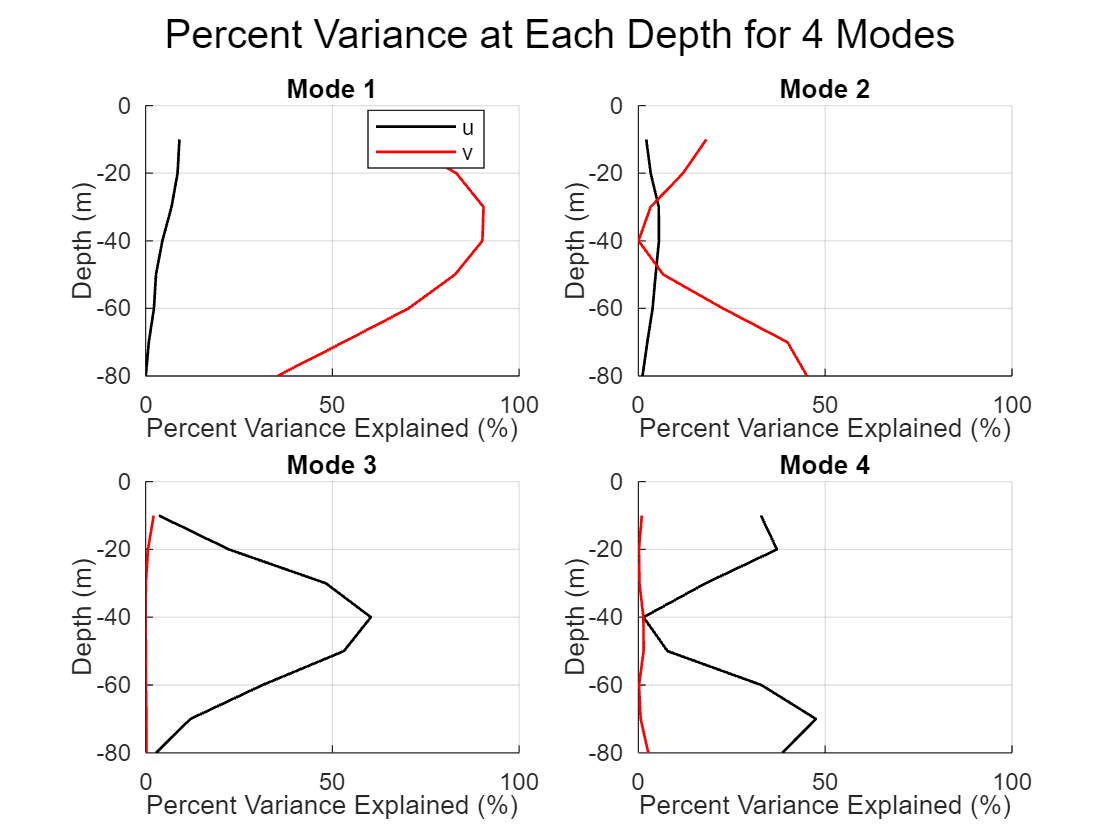

Cu=diag(C(1:8,1:8));
Cv=diag(C(9:16,9:16));

figure(6);
clf
for i = 1:4
    u_percent_var(:,i) = u_eof_amp(:,i).^2 * lambda(i)./Cu * 100;
    v_percent_var(:,i) = v_eof_amp(:,i).^2 * lambda(i)./Cv * 100;
    subplot(2, 2, i); % 2x2 grid
    hold on;
    plot(u_percent_var(:, i), depth, 'k-', 'LineWidth', 1, 'DisplayName', 'u'); % Plot u variance
    plot(v_percent_var(:, i), depth, 'r-', 'LineWidth', 1, 'DisplayName', 'v'); % Plot v variance
    hold off;

    set(gca, 'YDir', 'normal'); 
    xlabel('Percent Variance Explained (%)');
    ylabel('Depth (m)');
    title(['Mode ' num2str(i)]);
    xlim([0, 100]); 
    grid on

    % Add legend only for the first subplot
    if i == 1
        legend('show', 'Location', 'best');
    end
end

sgtitle('Percent Variance at Each Depth for 4 Modes');

**What current patterns are captured in the first 4 modes?  Q2: What do the EOF modes tell you about the time-depth variability of u and v?**

**Mode 1**: The u component shows that as depth increases, the amplitude gradually decreases, indicating a greater influence near the surface. The v component shows an increase in amplitude near the surface (0 to -20m), but then a decrease as the depth increases.

**Mode 2**: The u component maintains a consistent amplitude as depth increases. The v component, however, shows a significant decrease in amplitude as depth increases.

**Mode 3**: The u component decreases in amplitude from the surface to a depth of 40 m, then increases from 40 m to 80 m. The v component shows a consistent decrease in amplitude as depth increases.

**Mode 4**: The u component shows a consistent increase in amplitude as depth increases. The v component initially increases in amplitude from the surface to 40 m, then decreases from 40 m to 80 m.